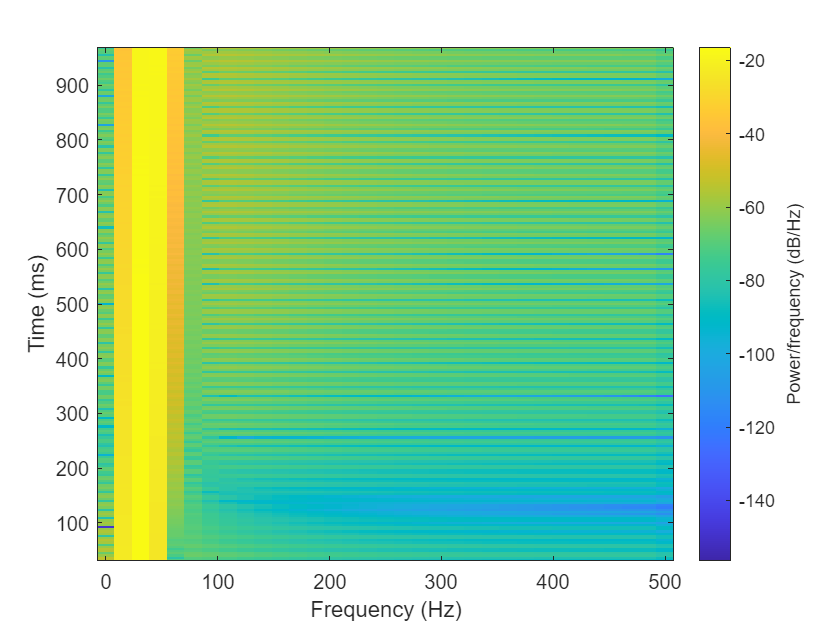

%EE451_Lab9 Dynamic Signal Spectra

Fs = 1000; %sampling rate
Ts = 1/Fs; %sampling time
t = 0:Ts:1; %this means a measuring of a single second

%first we need to create 4 cosines each with an amplitude of 1, and
%frequencies of 2, 4, 8, 16 each with a duration of 1 second.

%note that both of these require signal processing toolbox
c = chirp(t, 30, 1, 40);

spectrogram(c, 64, 60, 64, Fs);

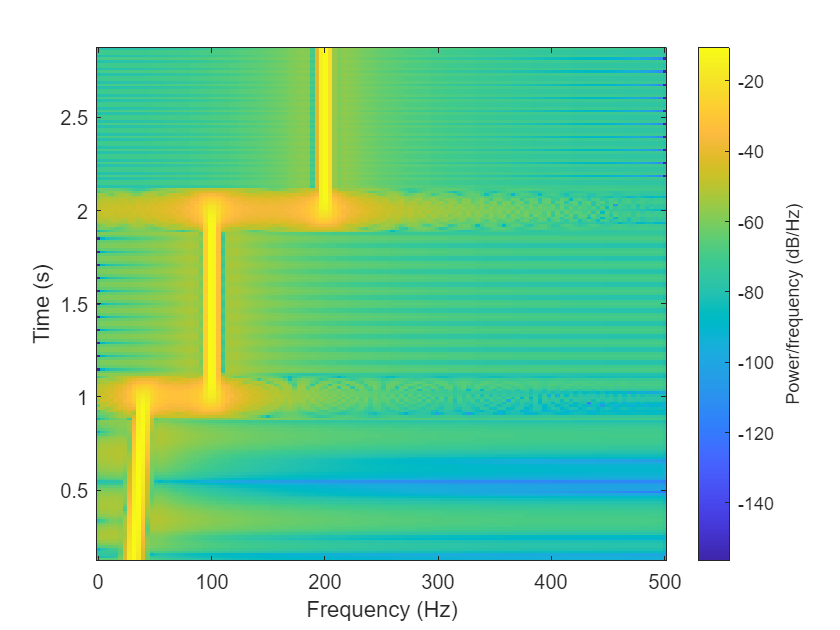

fs = 1000; ts = 1/fs;
t = 0:ts:1;
c2 = chirp(t, 300, 1, 400);

c1 = cos(2*pi*100*t);
c2 = cos(2*pi*200*t);
s = [c c1 c2];
spectrogram(s, 254, 240, 254, fs);


[A, f, t] = spectrogram (s, fs, 5, 60);
N = length(A(:,1));
%mesh(f,t,abs(A));


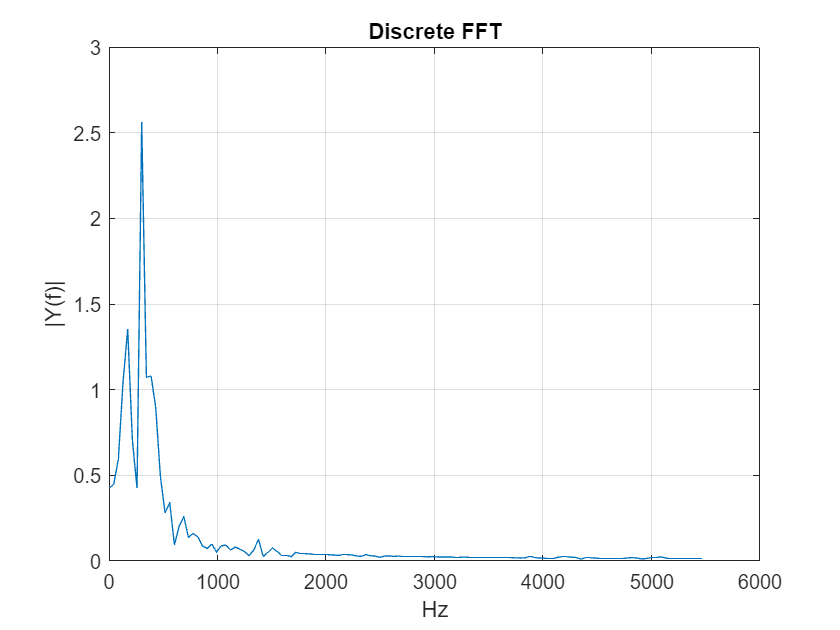

sh = figure;
sp = plot(zeros(1000, 1));
T = title("Discrete FFT");
xlabel('Hz');
ylabel('|Y(f)|');
grid on;

deviceReader = audioDeviceReader;
tic
while toc < 30
    mys = deviceReader();
    continuousFFT(mys, sp);
end